Create two detector

detectorInria = peopleDetectorACF('inria-100x41');
detectorCaltech = peopleDetectorACF('caltech-50x21');

Apply Detector

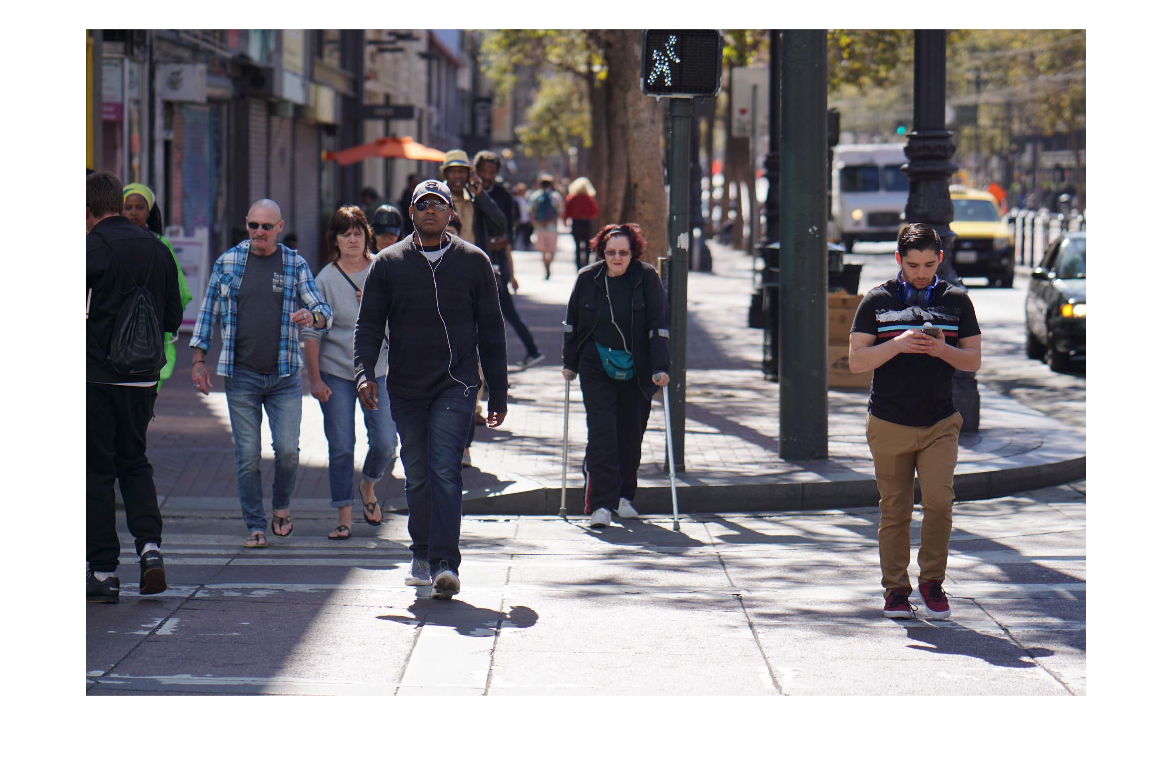

I = imread('P.jpg');
[bboxesInria,scoresInria] = detect(detectorInria,I,'SelectStrongest',false);
[bboxesCaltech,scoresCaltech] = detect(detectorCaltech,I,'SelectStrongest',false);
imshow(I);

Create Categorical Labels

labelsInria = repelem("inria",numel(scoresInria),1);
labelsInria = categorical(labelsInria,{'inria','caltech'});
labelsCaltech = repelem("caltech",numel(scoresCaltech),1);
labelsCaltech = categorical(labelsCaltech,{'inria','caltech'});

allBBoxes = [bboxesInria;bboxesCaltech];
allScores = [scoresInria;scoresCaltech];
allLabels = [labelsInria;labelsCaltech];

[bboxes,scores,labels] = selectStrongestBboxMulticlass(allBBoxes,allScores,allLabels,...
    'RatioType','Min','OverlapThreshold',0.65);

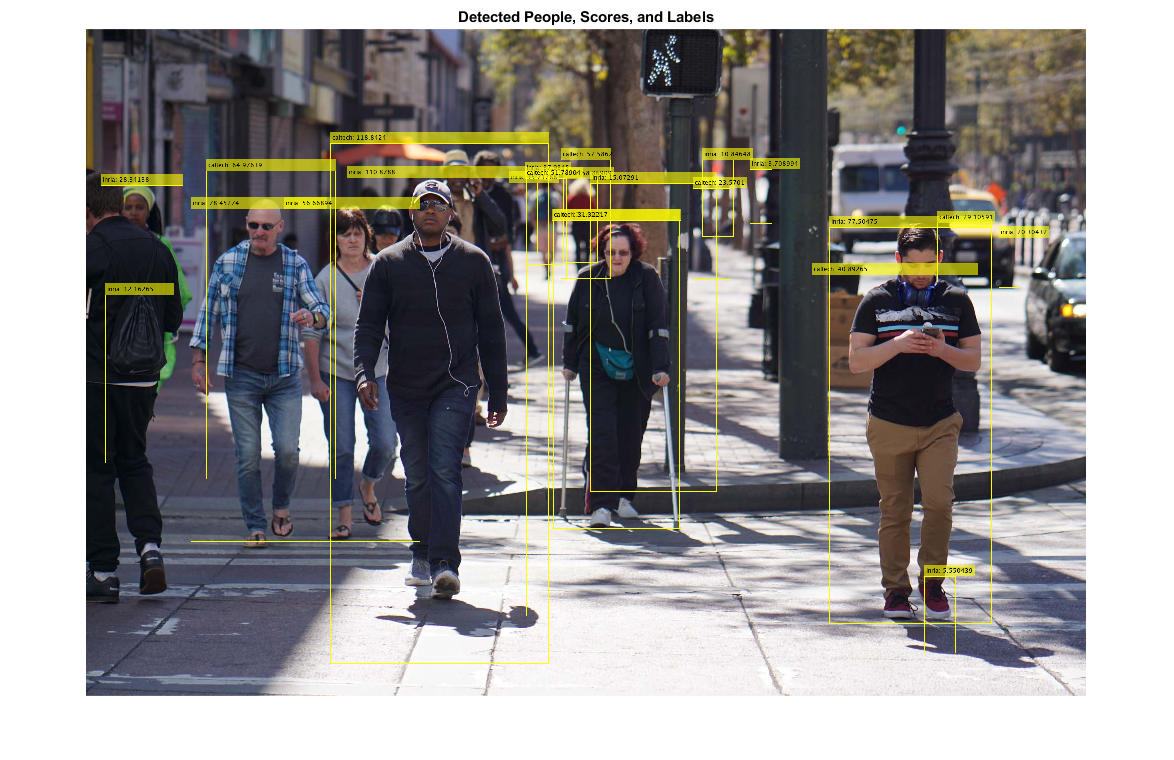

annotations = string(labels) + ": " + string(scores);
I = insertObjectAnnotation(I,'rectangle',bboxes,cellstr(annotations));
imshow(I)
title('Detected People, Scores, and Labels')